## Validate Protected Model

Folder: FMU_liv/LC_ctrl/test_harness

% Open model Controller
base_model = "LC_control";
open_system(base_model);

From **Simulation** tab select **Save** **> Save As..**. A dialog box opens where user can go to the *LC_ctrl\test_harness* folder and set the File name as *LC_control_harness*.

% Root path
rootPath = "C:\MATLAB\FMU_lib\";

% model path
mPath = rootPath + "LC_ctrl\test_harness\";
% Save model with a different name to avoid warnings when generating the protected model
model = base_model + "_harness";
save_system(base_model, mPath + model);

From the **Library Browser** add a *Model* block (Library>Simulink>Ports & Subsystems>Model). Double click on it and select the  *LC_ctrl\CB_core_control.slxp *protected model in* Model name. *Repeat the action for the *PF_core_control.slxp*

Modify the model as shown in the following figure:

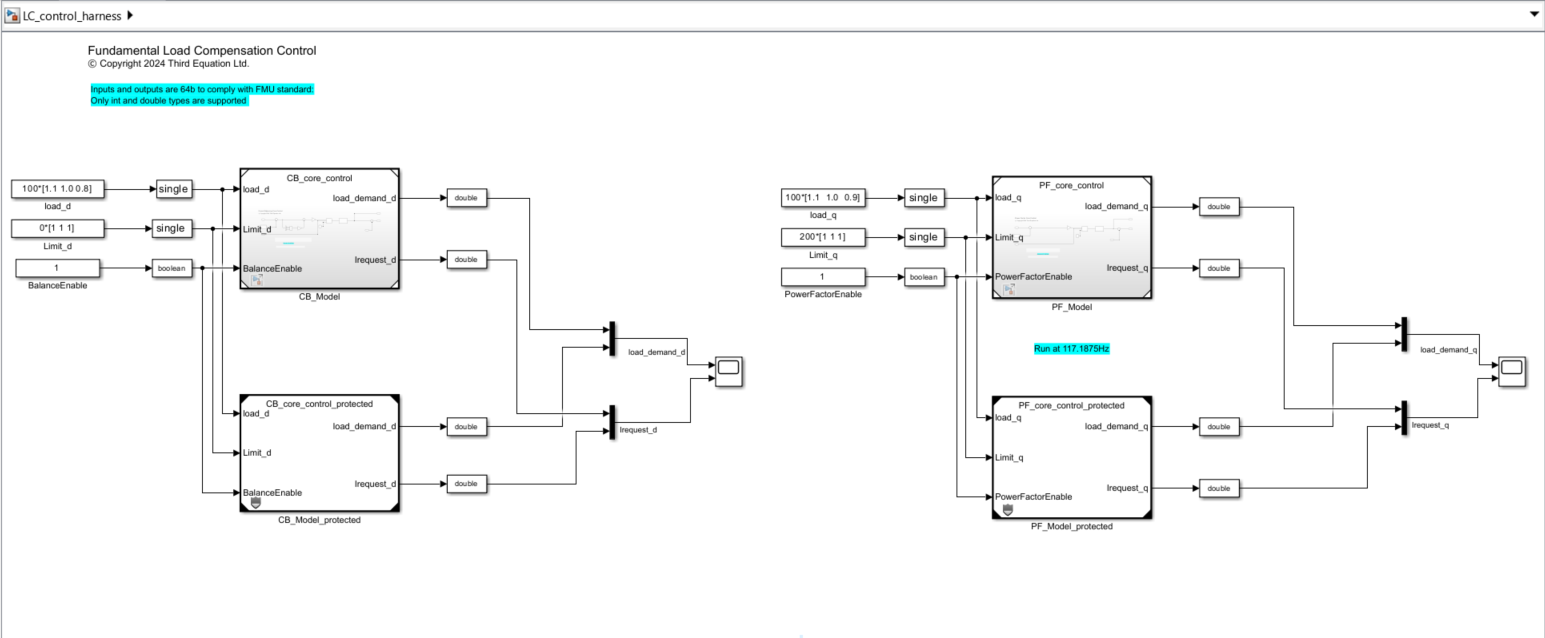

Note the *convert* blocks. They are included as the EC_core_control works with single presicion floats (32b)

Validation Requirements:

- Both blocks should deliver similar outputs when stimulated with similar inputs.

- Outputs shall be zero when input Enable is equal to 0 (false)

% close model after protected model is validated
close_system(model);

*Copyright 2024 Third Edquation Ltd.*